Consider the following multi-objective problem:


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & x_1^2 +x_2^2 -16x_1 -12x_2 ,-x_1 +2x_2 \\
s\ldotp t & x_1 +x_2 \le 10\\
 & x_1 \ge 0\\
 & x_2 \ge 0
\end{array}\right.$$


close all;
clear all;
clc;

matlab.lang.OnOffSwitchState = 1;

**a) Is it a convex problem? Why?**

We have to analyze individualy the convexity of each Objective Function and the constraints.

- Objective Function

-     
$$f_1 \left(x\right)=x_1^2 +x_2^2 -16x_1 -12x_2$$


-     
$$f_2 \left(x\right)=-x_1 +2x_2$$


On the case of $f_1 \left(x\right)$ we can recognize a quadratic function: $$f\left(x\right)=\frac{1}{2}x^T Q\;x+q^T x+b$$ . We need to check if $\nabla^2 f_1 \left(x\right)\ge 0$ . The Hessian Matrix has to be positive semi-definite to conclude if the function is convex or not. To check if the Hessian Matrix is positive semi-definite we need to check the eigen-values of Q are not-negative


$$H_1 =\left\lbrack \begin{array}{cc}
4 & 0\\
0 & 4
\end{array}\right\rbrack$$


With the second Objective function $f_2 \left(x\right)$ we can confirm is a linear function, which it means is convex.

- Constraints 

-     
$$g_1 \left(x\right)=x_1 +x_2 \le 10$$


-     
$$g_2 \left(x\right)=x_1 \ge 0$$


-     
$$g_3 \left(x\right)=x_2 \ge 0$$


The constraints functions $g_2 \left(x\right)\;$and $g_3 \left(x\right)$ are both linear inequalities and the feasible region belong to the non-negative Castersian plane, and it means is convex set.  

The constraint function $g_1 \left(x\right)$ is also linear inequality constraint and the region is defined by $x_1 +x_2 =10$, $x_1 =0$ and $x_2 =0$ makes a triangle set that is also convex.

Since all the objective functions and the feasible region are convex, we can confirm that this multi-objective optimization problem is convex.

% Evaluation of f1
H1 = [4 0
      0 4];

fprintf("Eigen-values Objective Function f1: ");

Eigen-values Objective Function f1: 

disp(eig(H1));

     4
     4



% Definition of the objective functions and the constraints
objective_function_1 = @(x1,x2) x1.^2 + x2.^2 - 16.*x1 - 12.*x2;
objective_function_2 = @(x1,x2) -x1 + 2.*x2;
constraint_1 = @(x1,x2) x1 + x2 - 10;
constraint_2 = @(x1,x2) -x1;
constraint_3 = @(x1,x2) -x2;

% Creation of the grid with x1 and x2
x1 = linspace(0,10, 100);
x2 = linspace(0,10, 100);
[X1,X2] = meshgrid(x1,x2);

% Evaluate the objective function and the feasible region
F1 = objective_function_1(X1,X2);
F2 = objective_function_1(X1,X2);
C1 = constraint_1(X1,X2);
C2 = constraint_2(X1,X2);
C3 = constraint_3(X1,X2);

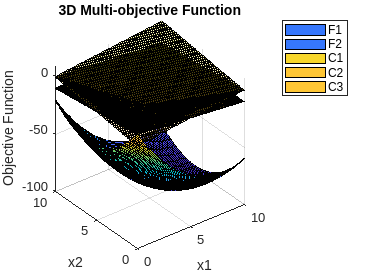

% Create 3D plot
figure;
surf(X1,X2,F1);
hold on
surf(X1,X2,F2);
surf(X1,X2,C1, 'FaceAlpha', 0.3);
surf(X1,X2,C2, 'FaceAlpha', 0.3);
surf(X1,X2,C3, 'FaceAlpha', 0.3);

xlabel("x1");
ylabel("x2");
zlabel("Objective Function");

legend("F1", "F2", "C1", "C2", "C3");
title("3D Multi-objective Function");

view(3);
hold off

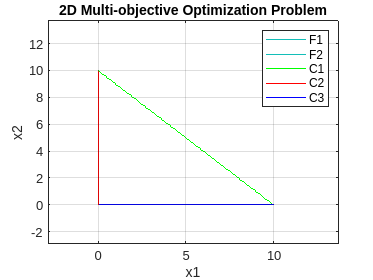

% Create 2D plot
figure;
contour(X1,X2,F1, [0 0]);
hold on
contour(X1,X2,F2, [0 0]);
contour(X1,X2,C1, [0 0], 'g-');
contour(X1,X2,C2, [0 0], 'r-');
contour(X1,X2,C3, [0 0], 'b-');

xlabel("x1");
ylabel("x2");

legend('F1', 'F2', 'C1', 'C2', 'C3');
xlim([-5 15]);
ylim([-5 15]);

title('2D Multi-objective Optimization Problem');
grid on

hold off

**b) Do minima exist? Why?**

**c) Is the point (5, 5) a minimum? Why?**

**d) Is the point (10, 0) a weak minimum? Why?**

**e) Find a subset of minima by using the scalarization method.**

**f) Find the set of all weak minima by using the scalarization method.**

**g) Find the set of all minima.**

**h) Find the ideal point.**